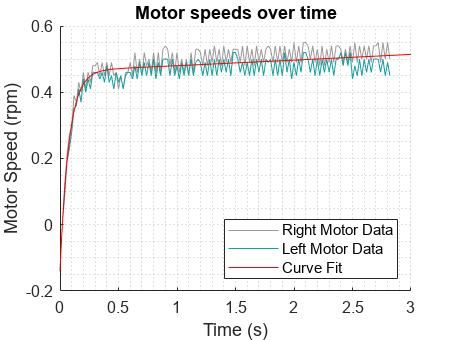

clear; clf; close all
set(0, 'DefaultLineLineWidth', 0.5);
my_color = [16 161 156]./255;
my_gray = [156 151 154]./255;

period = 20; % ms
sampling_rate = 1000/period;

data = csvread("motor_data_2.csv");
A = 1:size(data);
data(:,3) = repmat(A, 1, 1)./sampling_rate;
right_motor = data(:,1);
left_motor = data(:,2);
time = data(:,3);
right_test = [right_motor time];
left_test = [left_motor time];
combined_data = [right_test; left_test];

[fit_all, gof_all] = fit(combined_data(:,2), combined_data(:,1), 'exp2');

figure(1)
hold on
plot(time, right_motor, "LineWidth", 0.5, "Color", my_gray)
plot(time, left_motor, "LineWidth", 0.5, "Color", my_color)
plot(fit_all, 'r')
legend('Right Motor', 'Left Motor', 'Curve Fit', 'location', 'southeast')
title("Motor speeds over time"); legend("Right motor", "Left motor"); grid minor
xlabel("Time (s)"); ylabel("Motor Speed (rpm)")
legend('Right Motor Data', 'Left Motor Data', 'Curve Fit')

% Parameters
V_step = 300;

syms K tau s t
M_s = (K/tau)/(s+(1)/(tau));
F = M_s * (V_step)/(s);

f = ilaplace(F)

$$f = 300\,K-300\,K\,{\mathrm{e}}^{-\frac{t}{\tau }}$$


% Curve fit from cftool
curve_fit = 0.464*exp(0.03429*t) - 0.604*exp(-13.24*t);
% Approximated curve
curve_fit = 0.464 - 0.604*exp(-13.24*t)

$$curve\_fit = \frac{58}{125}-\frac{151\,{\mathrm{e}}^{-\frac{331\,t}{25}}}{250}$$


K_calc = (58/125)/300;
tau_calc = 25/331

tau_calc = 0.0755

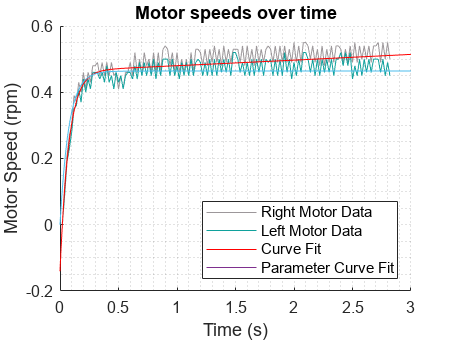


% Plot curve fit with calculated parameters
% fplot(0.464*exp(0.03429*t) - 0.6042*exp(-13.24*t), [0 3])
fplot(subs(subs(f,K,K_calc), tau, tau_calc), [0 3]);
legend('Right Motor Data', 'Left Motor Data', 'Curve Fit', "Parameter Curve Fit")